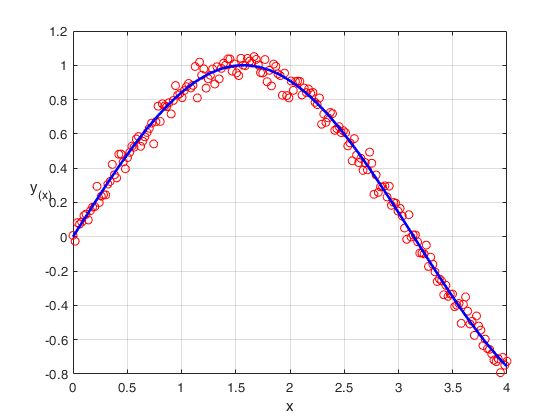

clear;
% func = @(x) (sin(3.*x+2));              % funkce pro nagenerování dat
% func = @(x) (sin(pi.*x))./((x.^2)+1);   % funkce pro nagenerování dat
from = 0;                               % rozsah pro od ...
to = 4;                                 % ... do pro nagenerování dat
N =  200;                               % počet vzorků
func = @(x) (sin(x));
x = from:((to-from)/(N-1)):to;          % vzorkovací čas
y = awgn(func(x),27);                   % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)
plot(x,y,'or');
hold on;
grid on;
xlabel("x");
ylabel("y_{(x)}","Rotation",0);
plot(from:((to-from)/(N*10-1)):to,func(from:((to-from)/(N*10-1)):to),'-b',"LineWidth",2);
hold off;

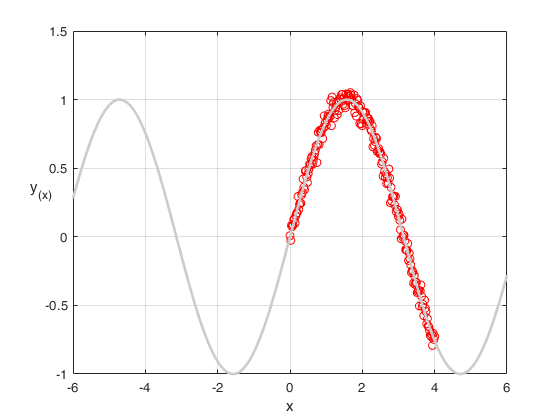

from = -6;                               % rozsah pro od ...
to = 6;   
plot(x,y,'or');
hold on;
grid on;
xlabel("x");
ylabel("y_{(x)}","Rotation",0);
plot(from:((to-from)/(N*10-1)):to,func(from:((to-from)/(N*10-1)):to),"LineWidth",2,"Color",[0.8 0.8 0.8]);
hold off;

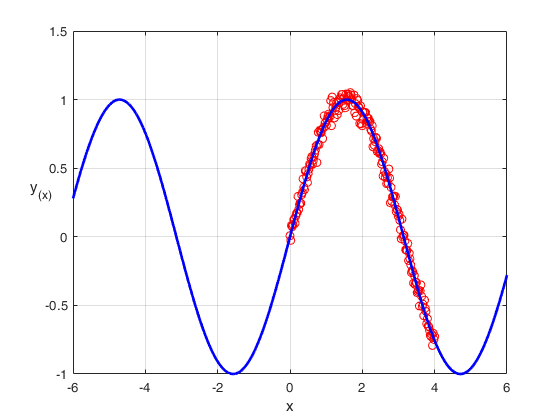

plot(x,y,'or');
hold on;
grid on;
xlabel("x");
ylabel("y_{(x)}","Rotation",0);
plot(from:((to-from)/(N*10-1)):to,func(from:((to-from)/(N*10-1)):to),'b-',"LineWidth",2);



csvwrite('input_data.csv',[x;y]); 